# **Uninfected**

## **GLOBULOS BLANCOS**

### **a) Anotaciones**

close all; clc; clearvars;
% Cargar carpeta del 1º paciente
imageFolder='C:\Users\ASUS\Documents\3ºMondragon Universidad\6º Semestre\PBL 6\Procesamiento\Dataset\Uninfected\NIH-NLM-ThickBloodSmearsU\Uninfected Patients\TF201_HT6\tiled'; 

% Cargar imagenes del 1º paciente
imageFiles=dir(fullfile(imageFolder, '*.tiff'));

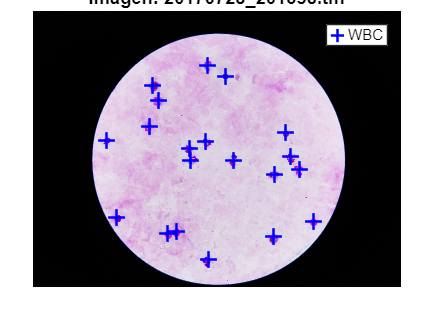

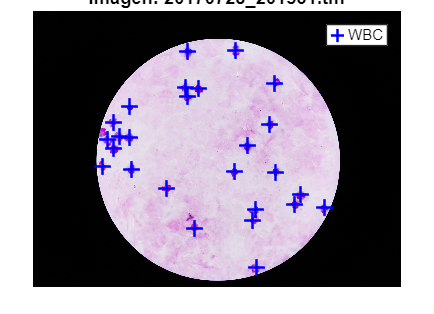

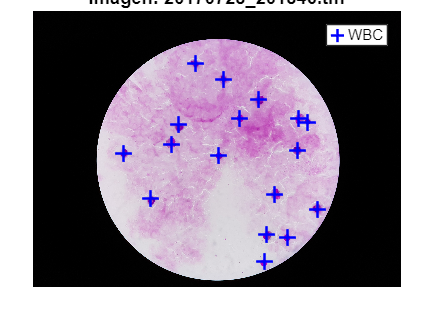

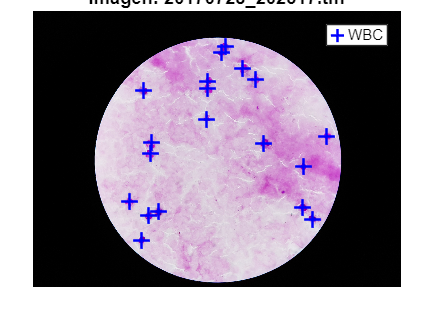

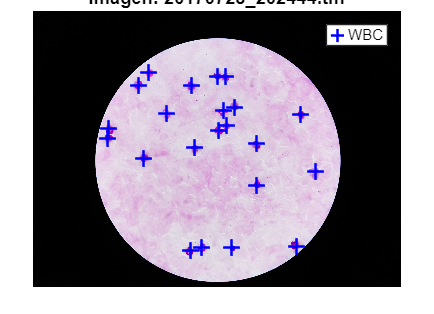

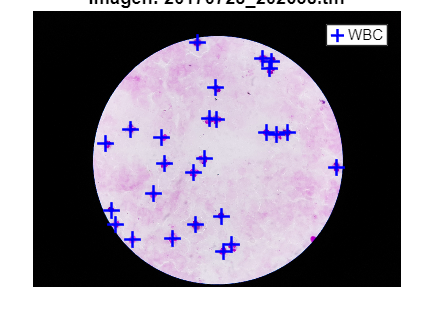

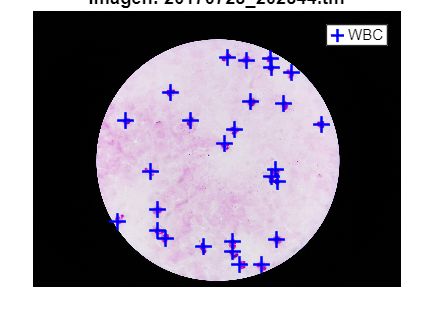

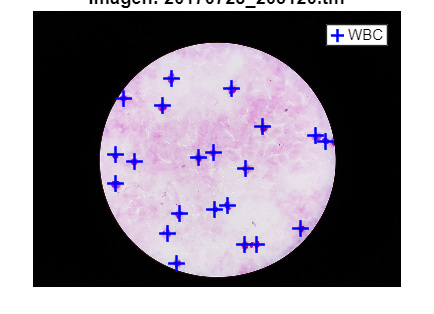

for i = 1:length(imageFiles)
    % Nombre completo del archivo
    filename=fullfile(imageFolder, imageFiles(i).name);

    % Cargar la imagen
    I=imread(filename);
    figure;
    imshow(I); hold on;

    % Carpetas de las anotaciones
    ruta_GT = fullfile('C:\Users\ASUS\Documents\3ºMondragon Universidad\6º Semestre\PBL 6\Procesamiento\Dataset\Uninfected\NIH-NLM-ThickBloodSmearsU\Annotations\TF201_HT6\results\2546', [imageFiles(i).name(1:end-5), '.txt']);
    
    % Datos de cada carpeta
    datos = readtable(ruta_GT, 'Delimiter', ',', 'HeaderLines', 1);

    % ===== GLÓBULOS BLANCOS =====
    solo_WBC = datos(strcmp(datos.Var2, 'White_Blood_Cell'), :);
    x_wbc = solo_WBC.Var6;
    y_wbc = solo_WBC.Var7;
    plot(x_wbc, y_wbc, 'b+', 'MarkerSize', 10, 'LineWidth', 1.5);  % cruces azules

    title(['Imagen: ', imageFiles(i).name], 'Interpreter', 'none');
    legend('WBC');
    hold off;
end

### **b) 3º Modelo K-means Color**

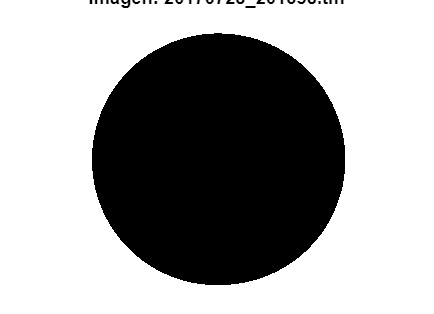

numero_de_wbc = 20

candidatos_a_wbc = 1

wbc_detectados = 0

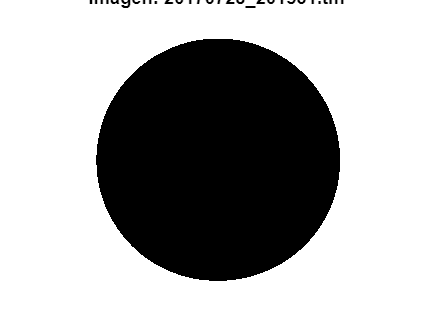

numero_de_wbc = 26

candidatos_a_wbc = 1

wbc_detectados = 0

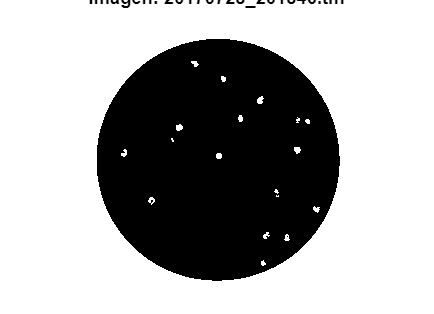

numero_de_wbc = 17

candidatos_a_wbc = 19

wbc_detectados = 16

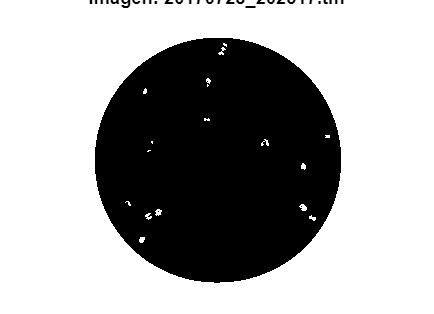

numero_de_wbc = 19

candidatos_a_wbc = 22

wbc_detectados = 16

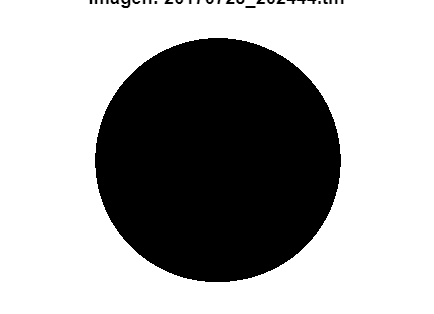

numero_de_wbc = 22

candidatos_a_wbc = 1

wbc_detectados = 0

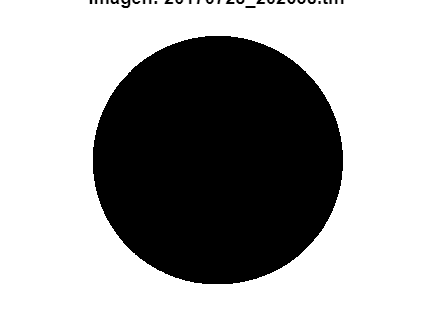

numero_de_wbc = 26

candidatos_a_wbc = 1

wbc_detectados = 0

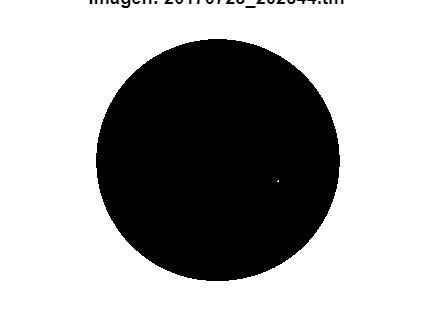

numero_de_wbc = 27

candidatos_a_wbc = 2

wbc_detectados = 1

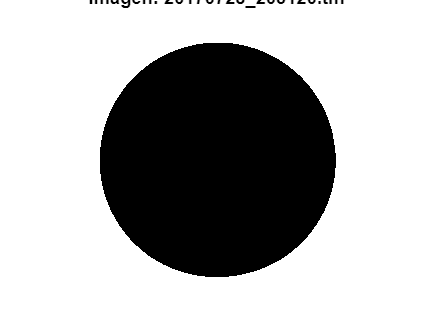

numero_de_wbc = 21

candidatos_a_wbc = 1

wbc_detectados = 0

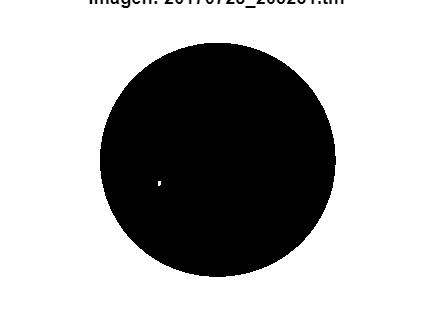

numero_de_wbc = 20

candidatos_a_wbc = 2

wbc_detectados = 1

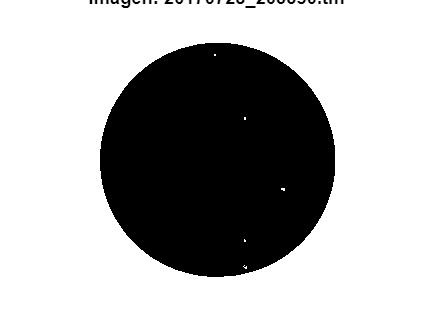

numero_de_wbc = 27

candidatos_a_wbc = 6

wbc_detectados = 5

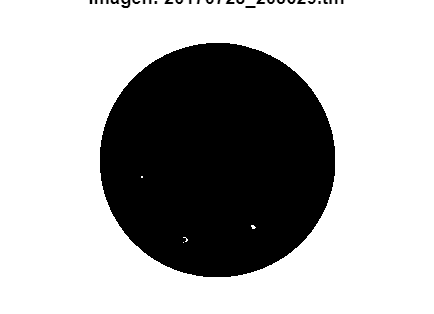

numero_de_wbc = 26

candidatos_a_wbc = 4

wbc_detectados = 3

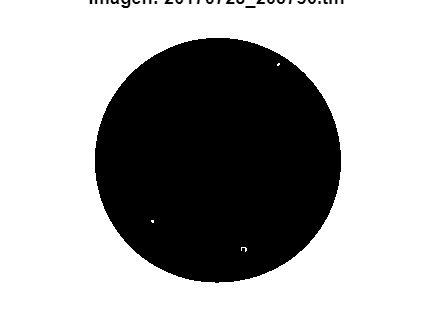

numero_de_wbc = 21

candidatos_a_wbc = 4

wbc_detectados = 3

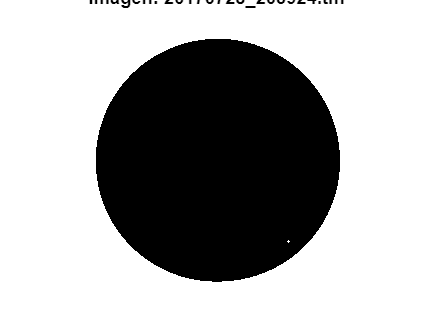

numero_de_wbc = 29

candidatos_a_wbc = 2

wbc_detectados = 1

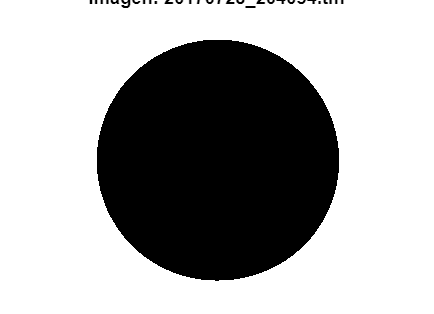

numero_de_wbc = 32

candidatos_a_wbc = 1

wbc_detectados = 0

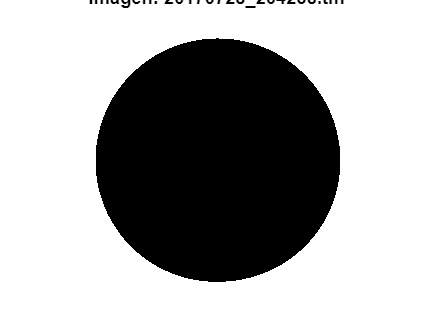

numero_de_wbc = 18

candidatos_a_wbc = 1

wbc_detectados = 1

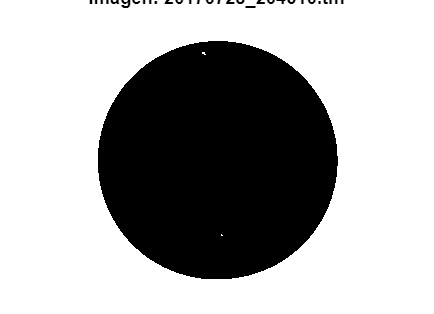

numero_de_wbc = 31

candidatos_a_wbc = 3

wbc_detectados = 2

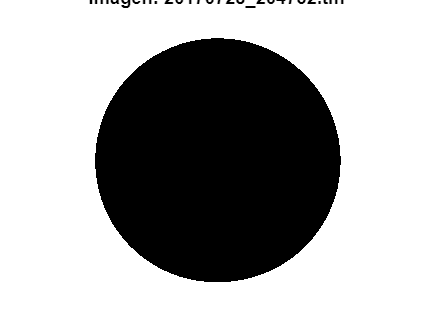

numero_de_wbc = 28

candidatos_a_wbc = 1

wbc_detectados = 0

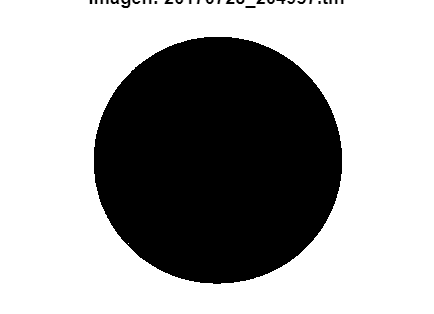

numero_de_wbc = 27

candidatos_a_wbc = 1

wbc_detectados = 0

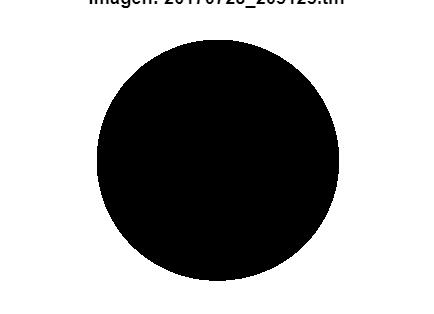

numero_de_wbc = 29

candidatos_a_wbc = 1

wbc_detectados = 0

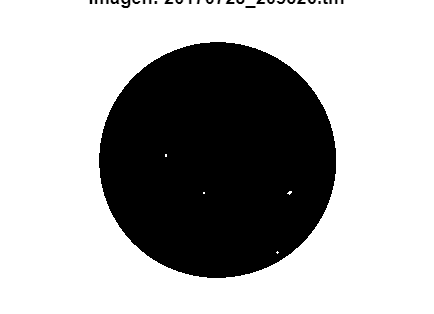

numero_de_wbc = 21

candidatos_a_wbc = 5

wbc_detectados = 3

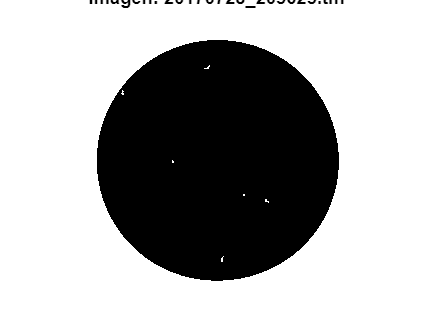

numero_de_wbc = 30

candidatos_a_wbc = 7

wbc_detectados = 6

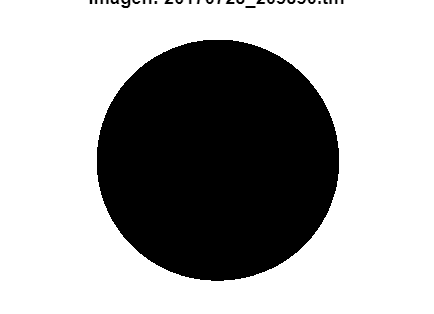

numero_de_wbc = 23

candidatos_a_wbc = 1

wbc_detectados = 0

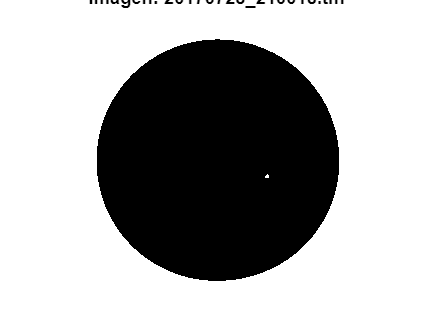

numero_de_wbc = 19

candidatos_a_wbc = 2

wbc_detectados = 1

total_wbc_reales = 0;
total_candidatos = 0;
total_wbc_detectados = 0;
for i = 1:length(imageFiles)
    % Nombre completo del archivo
    filename=fullfile(imageFolder, imageFiles(i).name);

    % Cargar la imagen
    I=imread(filename);
    
    % Binario y escala de grises
    I_gray=rgb2gray(I);
    
    % Filtro
    I_sinruido=medfilt2(I_gray, [3 3]);

    % Aplicar imsegkmeans directamente (necesita uint8 o single)
    [L, cluster_centers] = imsegkmeans(I_sinruido, 3);

    mean_intensity = zeros(3,1);
    for c = 1:3
        mean_intensity(c) = mean(I_sinruido(L==c), 'all');
    end
    [~, idx_darkest] = min(mean_intensity);
    dark_points_mask = L == idx_darkest;
    
    % === Filtrar WBC (regiones grandes) ===
    globulos_blancos = bwareaopen(dark_points_mask, 500);
    
    % Visualiza la máscara final
    figure;
    imshow(globulos_blancos);hold on;
    title(['Imagen: ', imageFiles(i).name], 'Interpreter', 'none');
    
    % Carpetas de las anotaciones
    ruta_GT = fullfile('C:\Users\ASUS\Documents\3ºMondragon Universidad\6º Semestre\PBL 6\Procesamiento\Dataset\Uninfected\NIH-NLM-ThickBloodSmearsU\Annotations\TF201_HT6\results\2546', [imageFiles(i).name(1:end-5), '.txt']);
    
    % Datos de cada carpeta
    datos = readtable(ruta_GT, 'Delimiter', ',', 'HeaderLines', 1);

    % ===== GLÓBULOS BLANCOS =====
    solo_WBC = datos(strcmp(datos.Var2, 'White_Blood_Cell'), :);
    x_wbc = solo_WBC.Var6;
    y_wbc = solo_WBC.Var7;

    % ============Verificar el modelo========
    
    % Extraer el numero de wbc
    tamano=size(solo_WBC);
    numero_de_wbc = tamano(1,1)
    n=8;
    % Candidatos a wbc
    CC_2 = bwconncomp(globulos_blancos,n);
    properties_2 = {'Centroid', 'Circularity', 'Area','Eccentricity', 'Solidity'};
    caracteristicas = regionprops(CC_2,properties_2);
    tamano=size(caracteristicas);
    candidatos_a_wbc=tamano(1,1)

    % wbc detectados
    umbral_distancia = 50;
    wbc_detectados = 0;

    % Lista para guardar cuáles detecciones ya fueron usadas
    detectados_usados = false(length(caracteristicas), 1);

    % Recorrer cada wbc real
    for p = 1:length(x_wbc)
        centro_real = [x_wbc(p), y_wbc(p)];
        for d = 1:length(caracteristicas)
            if detectados_usados(d)
            continue;  % Saltar si esta detección ya fue usada
            end
            centro_detectado = caracteristicas(d).Centroid;
            distancia = norm(centro_real - centro_detectado);
            if distancia < umbral_distancia
                wbc_detectados = wbc_detectados + 1;
                detectados_usados(d) = true;
                break;  % Evita contar un wbc detectado más de una vez
            end
        end
    end
    % Mostrar wbc detectados
    wbc_detectados

    % Sumas de los wbc reales, candidatos y detectados 
    total_wbc_reales = total_wbc_reales + numero_de_wbc;
    total_candidatos = total_candidatos + candidatos_a_wbc;
    total_wbc_detectados = total_wbc_detectados + wbc_detectados;
end


% Analizar modelo con estos resultados
total_wbc_reales

total_wbc_reales = 559

total_candidatos

total_candidatos = 89

total_wbc_detectados

total_wbc_detectados = 59


% Confusion matrix
TP=total_wbc_detectados;
FP=total_candidatos-total_wbc_detectados;
FN=total_wbc_reales-total_wbc_detectados;

sensitivity=(TP/(TP+FN))*100

sensitivity = 10.5546

precision=(TP/(TP+FP))*100

precision = 66.2921